%% Description

% This program draws equidensity lines.



%% Housekeeping
% addpath('C:\Users\Parth Patel\Documents\GitHub\Image-Processing\Matlab-Functions-Image-Processing');
addpath('C:\Users\Elder\Documents\GitHub\Image-Processing-Parth\Matlab-Functions-Image-Processing');

%% Load a sample data file
im1.name = '02-12-2016_21_18_37_top.fits';
% im1.path = fullfile('D:\Dropbox Sync\Dropbox (MIT)\BEC1\Image Data and Cicero Files\Data - Raw Images\2016\2016-02\2016-02-12',im1.name);
im1.path = fullfile('J:\Elder Backup Raw Images\2016\2016-02\2016-02-12',im1.name);
disp(im1.path);

J:\Elder Backup Raw Images\2016\2016-02\2016-02-12\02-12-2016_21_18_37_top.fits


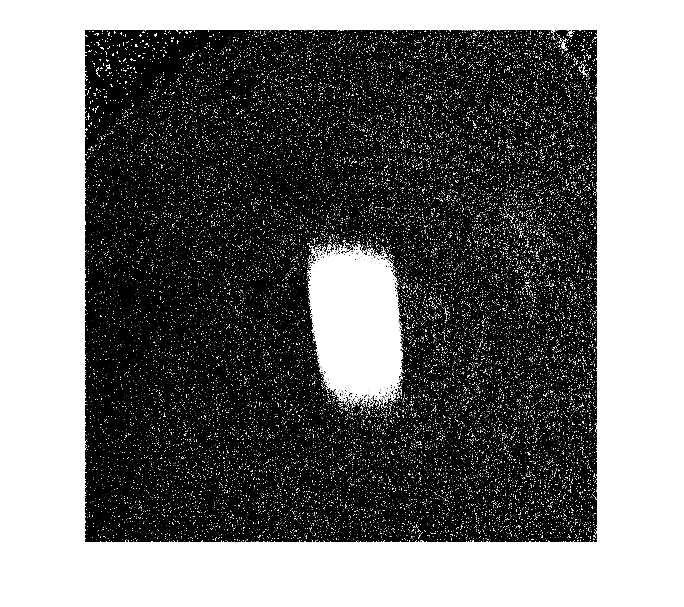

[~,im1.alldata] = load_img(im1.path); 
im1.OD = im1.alldata{1};
im1.wa = im1.alldata{3};
im1.woa = im1.alldata{4};
im1.dark = im1.alldata{5};
imshow(im1.OD,[0 0.05]); set(gca,'YDir','normal');

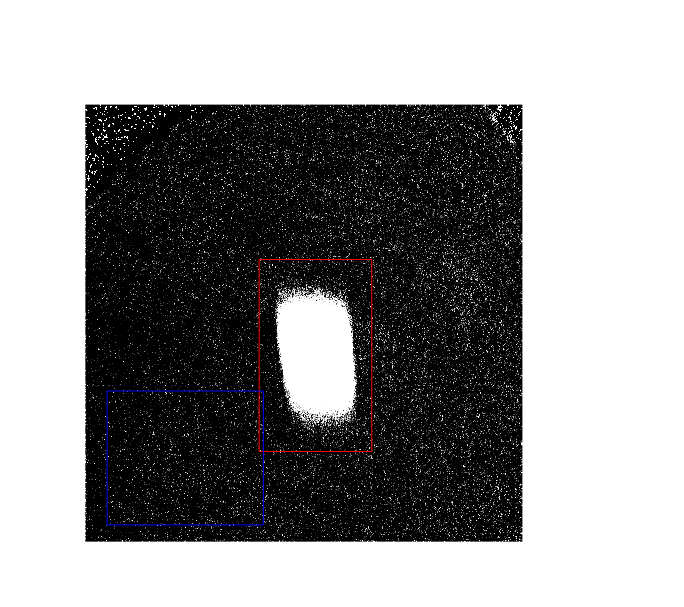

%% Clean up image
im1.roi_rect = [204,106,132,225]; % [xmin ymin width height]
im1.roi_data = imcrop(im1.OD,im1.roi_rect);
if 0 || ~isfield(im1,'roi_rect'), [im1.roi_data,im1.roi_rect] = imcrop(im1.OD); end % [204.51,106.51,131.98,210.98]
im1.bg_rect = [26,20,183, 157];
im1.bg_data = imcrop(im1.OD,im1.bg_rect);
if 0 || ~isfield(im1,'bg_rect'), [im1.bg_data,im1.bg_rect] = imcrop(im1.OD); end % [26,20,183, 157]

figure; hold on;
imshow(im1.OD,[0 0.1]); set(gca,'YDir','normal');
rectangle('Position',im1.roi_rect,'FaceColor','none','EdgeColor','red'); 
rectangle('Position',im1.bg_rect,'FaceColor','none','EdgeColor','blue'); hold off;

im1.bg_value = mean(im1.bg_data(:));
im1.cleanOD = im1.roi_data - im1.bg_value;
disp(['Backgroun subtracted: ', num2str(im1.bg_value)]);

Backgroun subtracted: -0.065835


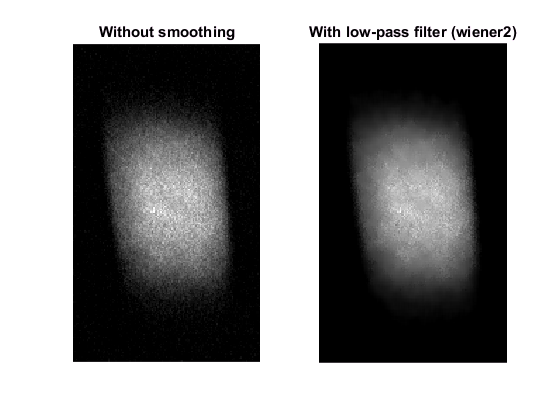

%% Contour plotting
figure;
im1.smoothdata = wiener2(im1.roi_data,[6 6]);
subplot(1,2,1); imshow(im1.roi_data,[0,1.5]); set(gca,'YDir','normal'); title('Without smoothing');
subplot(1,2,2); imshow(im1.smoothdata,[0 1.5]); set(gca,'YDir','normal'); title('With low-pass filter (wiener2)');

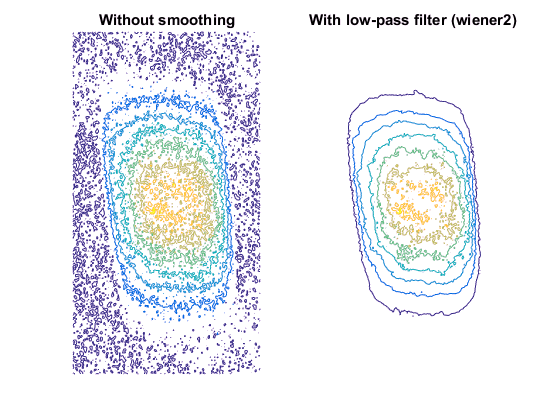

figure;
subplot(1,2,1); contour(im1.roi_data,8); axis off; title('Without smoothing');
subplot(1,2,2); contour(im1.smoothdata,8); axis off; title('With low-pass filter (wiener2)');

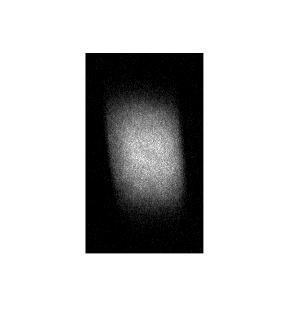

%% Fit circles on each row within some range
im1.ycut_range = (70:166)';
if 0 || ~isfield(im1,'leftedge')
    im1.leftedge = ones(size(im1.ycut_range));
    im1.rightedge = ones(size(im1.ycut_range));
    for i = 1:size(im1.ycut_range,1)
        y = im1.roi_data(im1.ycut_range(i),:);
        x = 1:1:size(y,2);
        [im1.leftedge(i),im1.rightedge(i)] = diskfit_topimg(x,y);
    end
end

% Plots
figure; hold on; ax1 = subplot(1,1,1);
imshow(im1.roi_data,[0,1.5]); set(ax1,'YDir','normal');

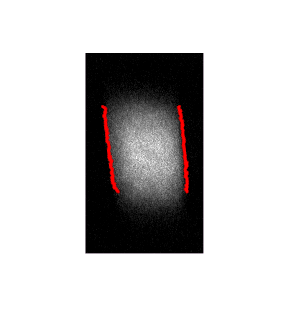

for i = 1:size(im1.ycut_range,1)
    plot(ax1,im1.leftedge(i),im1.ycut_range(i),'r.');
    plot(ax1,im1.rightedge(i),im1.ycut_range(i),'r.');
end

hold off;

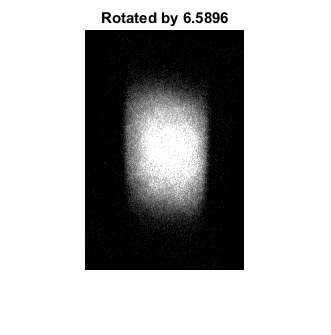

%% Fit lines to the edges and rotate image
xl = im1.leftedge;
yl = im1.ycut_range;
xr = im1.rightedge;
yr = im1.ycut_range;
% Fit lines for this data and enter the results here
im1.leftedge_slope = -7.023;
im1.rightedge_slope = -10.29;
im1.rotate_angle = - atan( 1/ ((im1.leftedge_slope + im1.rightedge_slope)/2)) * 180/pi;
im1.rotate_data = imrotate(im1.roi_data,im1.rotate_angle);
figure; imshow(im1.rotate_data); set(gca,'YDir','normal'); title(['Rotated by ',num2str(im1.rotate_angle)]);

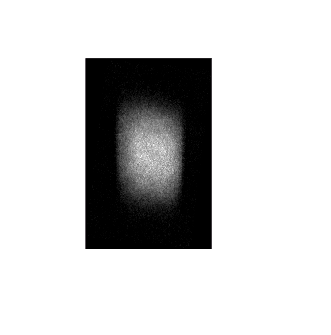

%% Find new edges
im1.rotate_ycut_range = (75:165)';
if 0 || ~isfield(im1,'rotate_leftedge')
    im1.rotate_leftedge = ones(size(im1.rotate_ycut_range));
    im1.rotate_rightedge = ones(size(im1.rotate_ycut_range));
    for i = 1:size(im1.rotate_ycut_range,1)
        y = im1.rotate_data(im1.rotate_ycut_range(i),:);
        x = 1:1:size(y,2);
        [im1.rotate_leftedge(i),im1.rotate_rightedge(i)] = diskfit_topimg(x,y);
    end
end

% Plots
figure; hold on; ax1 = subplot(1,1,1);
imshow(im1.rotate_data,[0,1.5]); set(ax1,'YDir','normal');

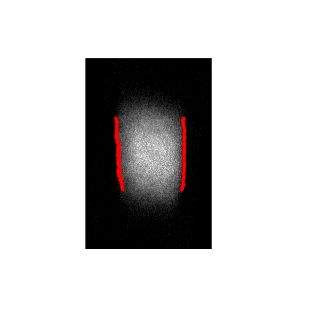

for i = 1:size(im1.rotate_ycut_range,1)
    plot(ax1,im1.rotate_leftedge(i),im1.rotate_ycut_range(i),'r.');
    plot(ax1,im1.rotate_rightedge(i),im1.rotate_ycut_range(i),'r.');
end

hold off;

xl = im1.rotate_leftedge;
yl = im1.rotate_ycut_range;
xr = im1.rotate_rightedge;
yr = im1.rotate_ycut_range;